%  Разбор данных
% запись путей
addpath(genpath('E:\ExchangeRateStability\MotorcycleBooks\Models'))

% Прописываем пути к данным
PathsDan=struct('Work', 'E:\ExchangeRateStability\Log', 'Home', 'E:\MotoDan\mU');
PathsDan.Work


danfiles=cell(1);
danfiles{1}="T1_2021-10-06";          % 1
danfiles{2}="T1_2021-10-06_1";        % 2
danfiles{3}="T1_2021-10-06_2";        % 3
danfiles{4}="T3_2021-10-08_10-33";    % 4
danfiles{5}="T4_2021-10-08_10-36";    % 5
danfiles{6}="T5_2021-10-08_10-44";    % 6  трамплин
danfiles{7}="T6_2021-10-08_11-28";     % 7  


%load('-mat', 'E:\MotoDan\mU\T1_2021-10-06')

%T1Load = LoadDan(PathsDan.Work, danfiles(2));
%T2Load = LoadDan(PathsDan.Work, danfiles(3));
T = LoadDan(PathsDan.Work, danfiles{5});



% Тест данных
titleDan = danfiles{5};
SetParamFFT = struct('step', 1, 'nfft', 128, 'limit', 64)  
SetParamInfo = struct('step', 1, 'nfft', 128, 'limit', 64)  


SetParamFFT = struct with fields:
     step: 1
     nfft: 128
    limit: 64


YawVel
YawAcc


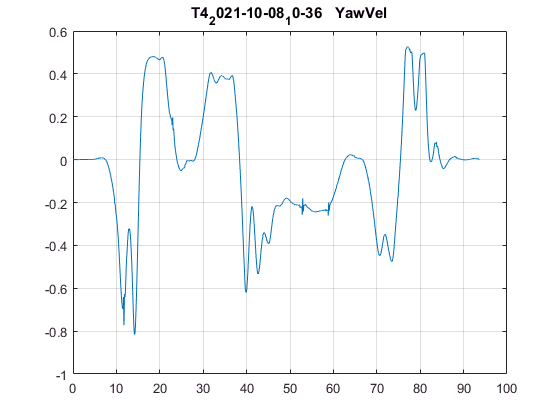

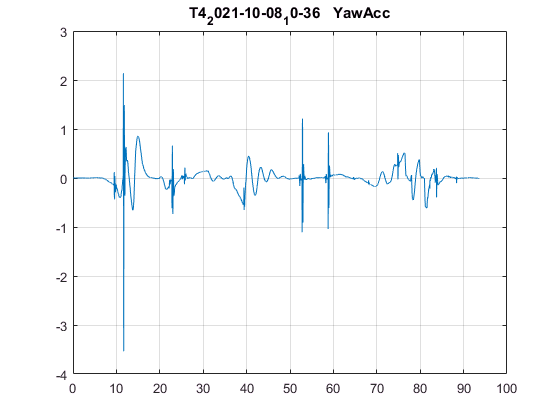

testDan = AnalysisDan(T, titleDan, "old");
%t5testDan.PlotXYZg(["PitchVel", "RollVel", "YawVel", "YawAcc"])
testDan.PlotXYZg(["YawVel", "YawAcc"])

XYZ.X
XYZ.Y
XYZ.Z


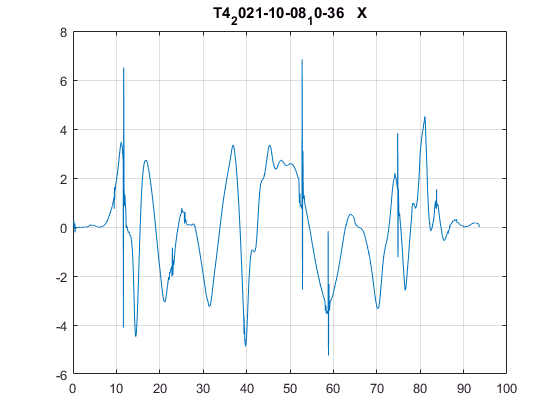

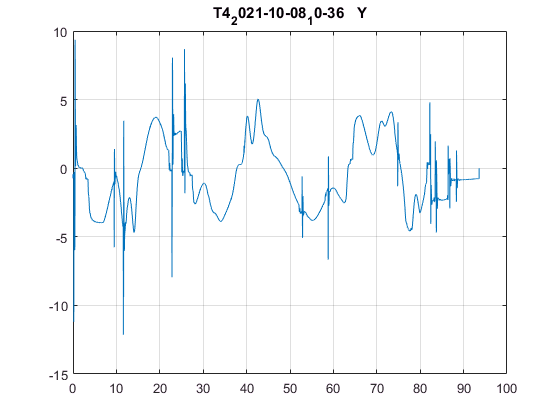

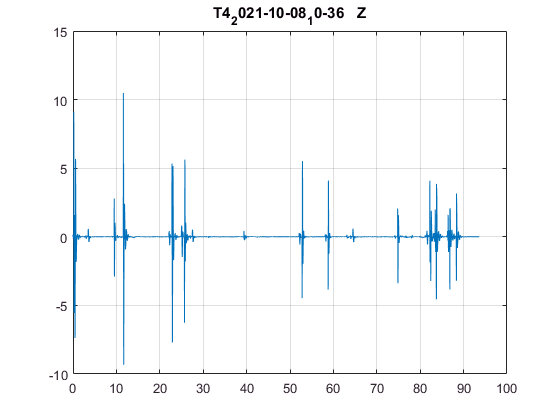

testDan.PlotXYZ(["X", "Y", "Z" ])

step = 1

nfft = 128

limit = 64

  -- spectrum  from data:


ss = "YawVel"

       YawVel


ss = "YawAcc"

       YawAcc


ss = "X"

       X


ss = "Y"

       Y


ss = "Z"

       Z


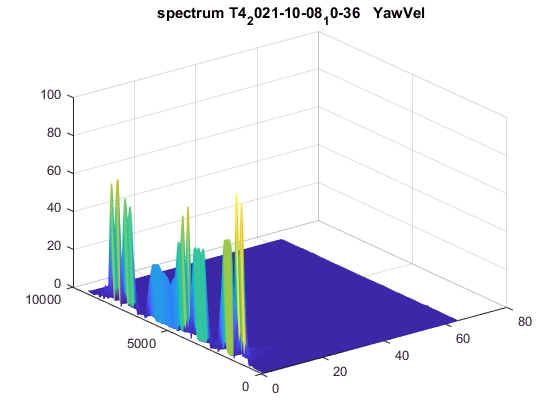

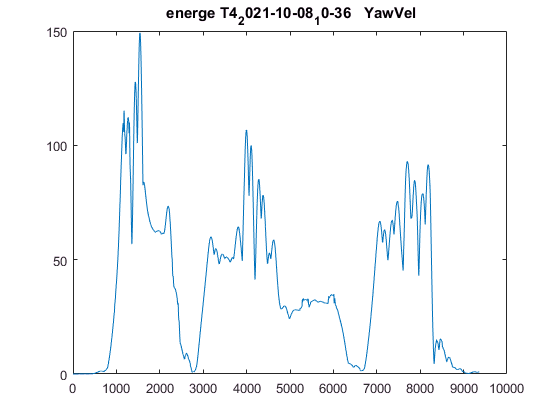

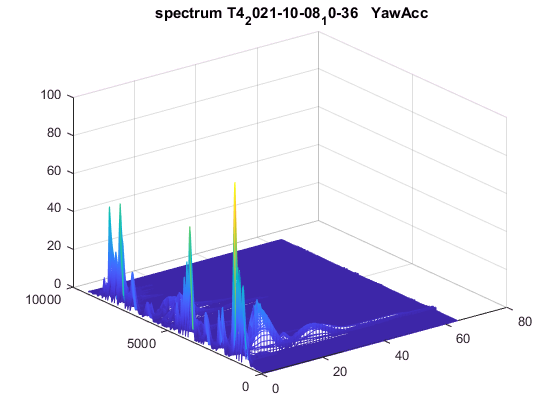

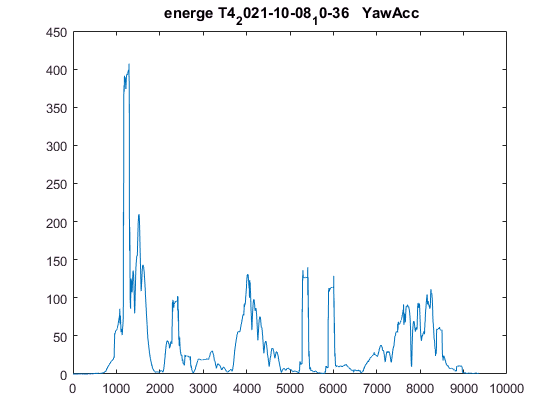

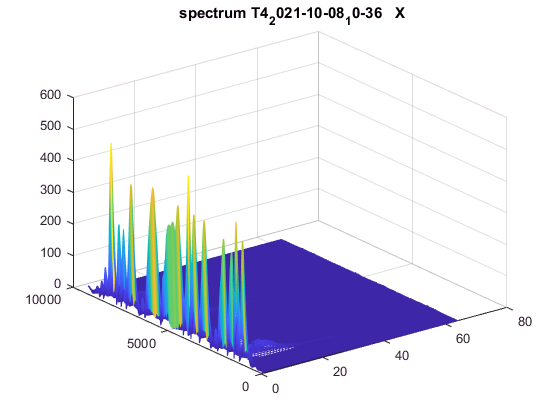

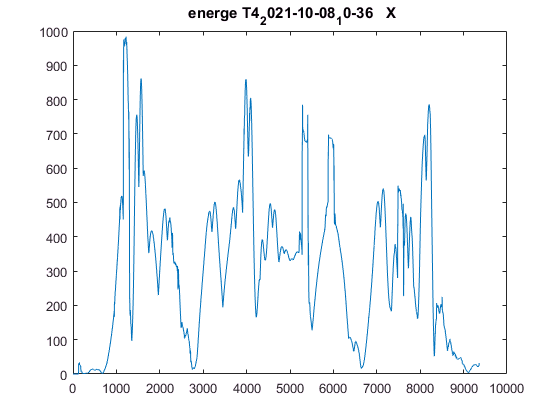

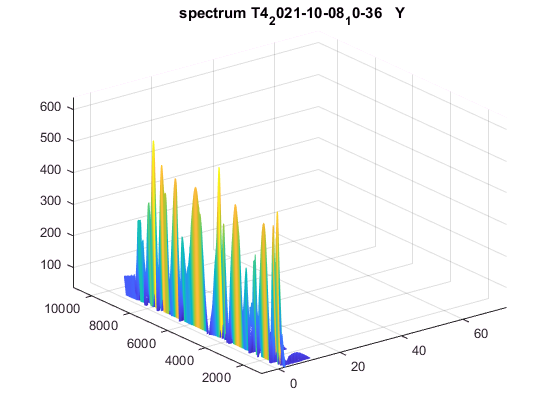

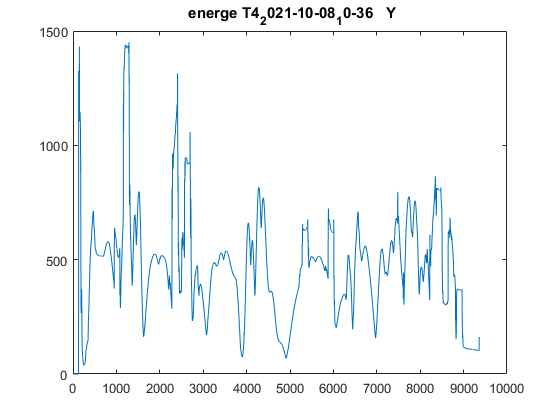

%[e, z]=testDan.Spectrum(["YawVel", "YawAcc", "X", "Y", "Z"], SetParamFFT)
zout=testDan.Spectrum(["YawVel", "YawAcc", "X", "Y", "Z"], SetParamFFT);

disp("----------")

----------


YY=T.XYZ.Y;
ZZ=T.XYZ.Z;
YY1= FiltrCheb(YY);
YawVel=T.XYZg.YawVel;
YawVel1= FiltrCheb(XX);


%   MyPlot  -> время   m-> массив   (1, array[N])..
%                                   (m, array[N])   
%                      mtitle [] сообщения [string1,... stringN]

m = zeros(4, length(T.Time));
m(1,:) = T.XYZg.PitchVel;
m(2,:) = mxx.RollVel;
m(3,:) = mxx.YawVel;
m(4,:) = mxx.YawAcc;
mtitle=["PitchVel", "RollVel", "YawVel", "YawAcc"];
plot1 = MyPlot(T6.Time, m, mtitle, "old");
plot1.AllPlot()


% Спестр

step = 1;
nfft = 128*1;

T6YawAccFFt = MyFFT01(T6.Time, T6.XYZg.YawAcc, step, nfft); 
fftT6AccFFt  = T6YawAccFFt.AllFFT();
[e,z]= T6YawAccFFt.AllFFTe()
figure
mesh(fftT6AccFFt)
title("YawAcc")

T6YawVelFFt = MyFFT01(T6.Time, T6.XYZg.YawVel, step, nfft); 
fftT6YawVel  = T6YawVelFFt.AllFFT();
figure
mesh(fftT6YawVel)
title("YawVel")




YAcc=DanConvert.XYZg.YawAcc';
YAccF = FiltrCheb(YAcc);
step=10;
Ms=zeros(step,1);

YAccFabs = abs(YAccF);
YAccF1 = zeros(length(YAccFabs),1);       % cumtrapz(abs(YAccF), 0.01);
for i =1: length(YAccFabs)
  Ms=[Ms(2:step); YAccFabs(i)];
  YAccF1(i) = sum(Ms);
end



% разность между колесами
disp("погрешность смещения")
z=DanConvert.vBelt.F - DanConvert.vBelt.R;
Vxerror=zeros(length(DanConvert.vBelt.F),1);
for i = 1:length(DanConvert.vBelt.F)
    Vxerror(i)= z(i)/max(DanConvert.vBelt.F(i), DanConvert.vBelt.R(i));
end
Vxerror(1:10)=0;

% тест формулы 1-(V/w*R)
r0 = 25.4*17/1000;
%V = DanConvert.speed;
V = DanConvert.vBelt.F;
kp=3;
%w0=2*pi*f
vr=r0*DanConvert.Engine.Rotv/kp;
s0 = 1-(V./(vr))
figure
plot(s0)
title("Проскальзование")

%  расчет mu

fx = DanConvert.Frc.X;
nx = DanConvert.Frc.Z;
muu = fx./nx
figure
plot(muu)
title("mU")


% филтер Калман

[x(:,3), x(:,2),  x(:,1)] = MasKalman(DanConvert.XYZg.RollVel');
[y(:,3), y(:,2),  y(:,1)] = MasKalman(DanConvert.XYZg.PitchVel');
[z(:,3), z(:,2),  z(:,1)] = MasKalman(DanConvert.XYZg.YawVel');
dt=0.01
for i = 1:length(x(:,1))
    state = [x(i,1); x(i,2); x(i,3); y(i,1); y(i,2); y(i,3); z(i,1); z(i,2); z(i,3)];
    m(i,:)= constacc(state, dt);
end






mx(:,1)=y(:,1);
mx(:,2)=m(:,4);
plot(mx,'DisplayName','mx')

% подключение FFT
step = 1;
nfft = 128*1;
limit = fix(nfft/2) % 64;
count = length(DanConvert.Time)
Npoint = fix(count/step);
t=linspace(1,limit, limit);
myFFT = MyFFT(DanConvert.Time, DanConvert.XYZg.YawAcc, step, nfft, limit); 

%myFFT = MyFFT(DanConvert.Time, YAccF, step, nfft, limit); 
k=1;
i=1
M=zeros(Npoint,limit);
M1=zeros(iCount,1);

V=zeros(Npoint,2);
Verror=zeros(Npoint,1);
while i<Npoint
%for i = 1:Npoint
    %timex=string(k*0.01)+" Sec."
    Y = myFFT.OneStep(k);
    M(i,:)=Y;
    M1(i)=sum(Y);
%    k0=k; if k0>count k0=count end
    %V(i, 1)=Dan1.vBelt.F(k0);
    %V(i, 2)=Dan1.vBelt.R(k0);
    %Verror(i)=(Dan1.vBelt.F(k0) -Dan1.vBelt.R(k0))/max(Dan1.vBelt.F(k0), Dan1.vBelt.R(k0));
%    figure;%    plot(t,Y)%    grid on;
    k=k+step;
    i=i+1;
end    

figure;
mesh(M)

figure
plot(M1)







nnnale = cell(1);

nnnale{1} = "11111"
nnnale{2} = "2222"
nnnale{3} = "33333"

nnnale{3}


z=cell(1,1);

for i=1:length(danfiles)
    dddz.ind=i;
    dddz.name=danfiles(i);
    z{i,1}=dddz;
end

function [z, vx, w] = MasKalman(w)
    function p=f0(w0)
        count = length(w0);
        vxx=[0.0; w0];
        vxx=vxx(1: count);
        p=vxx-w0;
    end
    vx=f0(w);
    z=f0(vx);
end

